# Neste Oyj: Modelling and Forecasting Monthly Stock Returns (Data Analysis and Modelling).

In this section, the objective is to identify and analyze patterns in historical stock returns over the past five years, spanning from **January 1, 2020 to December 31, 2024**, and to capture these patterns (trends) in order to forecast stock returns for the year **2025**.

To achieve the above, the data needs to be studied through a series of visualistaions, descriptive statistics and, tests. Through the visualisations, relevant patterns could be identified and guesses on what type of model could be used through the autocorrelation coefficient and partial autocorrelation coefficient function plots.

One of the fundamental requirement for an ARMA model to be used on a data set is for that data set to be weakly stationary that is a constant mean, constant variance over time (test for homoscedasticity: ARCH LM Test), and a constant autocovariance structure. With the descriptive statistics, the behaviour of the mean, Standard deviation, variance, skewness, and kurtosis can through more light on how the data is distributed. As for ARMA Models utilising compound returns, the data tend to be a lepokurtic(heavy tailed and peaked at its mean) distribution, mean close to zero, exhibits volatility clustering, and approximately symmetric. Hence to easily understand the distribution of the data, the jarque-bera test (null hypothesis: the tested data is mesokurtic that is normally distributed) Then for the autocovariance structure, it could be observed using the Ljung-Box test or from the acf and pacf plots.

Aside from the aforementioned tests and methods, a stationarity test such as Augmented Dickey Fuller Test could be to test for the presence of a unit root which indicates non-stationarity or a Kpss test whose null hypothesis indicates the presence of stationarity. If non-stationarity is observed, the differencing or detrending method cpould be used depending on the type of non-stationarity(Stochastic and Deterministic non-stationarity).

After all of these are done, the modelling phase can start. Using the Box-Jenkins, Firstly, the order of the model needs to be evaluated (is it an AR(q), MA(q),ARMA(p,q) or ARIMA(p,d,q)). This could be done by identifying the oder from the acf or pacf plots but given that visualisations can be a little hard to interprete so it is best to use an infromtion criterion (AIC and BIC). Then after that, the model can be estimated. After the model estimation, a model diagnostic checking can be done precisely on the residuals. 

In the diagnostic checking, all the tests and methods used in analysis the data before the model will still be used to evaluate the residuals (checking for autocorrelation, presence of white noise, distribution in the residuals).

To evaluate the performance of the forecasting model, a comparison will be done between the predicted value from the selected model and the actual stock returns for 2025 computed using closing price data obtained from **Investing.com**. This source was selected because alternative platforms such as **Yahoo Finance** and **Nasdaq.com** impose limitations on the historical time span of downloadable stock price data, typically restricting access to approximately one to one and a half years.

## Data Preparation.

in this part, the data is loaded into the analysis environment. The compound returns was already calculated using MS Excel (ln(Pt/Pt-1)) where Pt is the current value and Pt-1 is the previous value at the t-lag. The prepared excel file is loaded to MATLAB. The data runs from december 2024 to january 2020 (most current to oldest) and is the monthly return for the NESTE Oyj stock. 

data=xlsread('Neste Oyj Stock Price History.xlsx','Neste Oyj Stock_Ret Monthly','A2:H61');

%Extracting the return column

 neste_return=data(:,7);

Focusing solely on the seventh colun of the data possessing the returns, the analysis proceeded to understand the data better throug an exploratory analysis consist of the distribution of the returns, having a descriptive statistics(Mean, Median, skewnees, kurtosis, standard deviation, and variance)

## Data Exploratory Analysis.

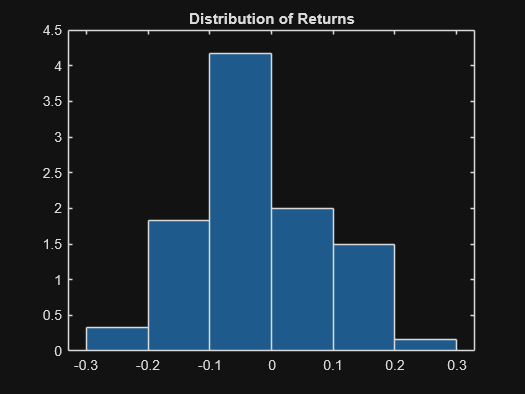

figure(1)
histogram(neste_return, 'Normalization','pdf')
title('Distribution of Returns')

%Descriptive Statistics
mean_r = mean(neste_return);
median_r = median(neste_return);
std_r = std(neste_return);
var_r = var(neste_return);
skew_r = skewness(neste_return);
kurt_r = kurtosis(neste_return);

% Display descriptive statistics
fprintf('Mean: %.6f\n', mean_r);

Mean: -0.018075


fprintf('Median: %.6f\n', median_r);

Median: -0.010510


fprintf('Std Dev: %.6f\n', std_r);

Std Dev: 0.102375


fprintf('Variance: %.6f\n', var_r);

Variance: 0.010481


fprintf('Skewness: %.4f\n', skew_r);

Skewness: 0.0016


fprintf('Kurtosis: %.4f\n', kurt_r)

Kurtosis: 2.6867


An initial examination of the return series shows that average returns are slightly negative, as both the mean and median are below zero. The standard deviation indicates noticeable variability, suggesting that returns are fairly volatile over the sample period. The distribution of returns is approximately symmetric, with skewness close to zero, while the kurtosis is slightly below three, implying a flatter distribution than the normal case and relatively few extreme values. The histogram supports these results by showing a broadly symmetric distribution centered around a small negative mean. These findings describe the unconditional properties of the data; however, they do not provide information about possible time dependence. Therefore, further analysis is required to test for autocorrelation and to assess whether ARMA models are appropriate for modeling the dynamics of returns.

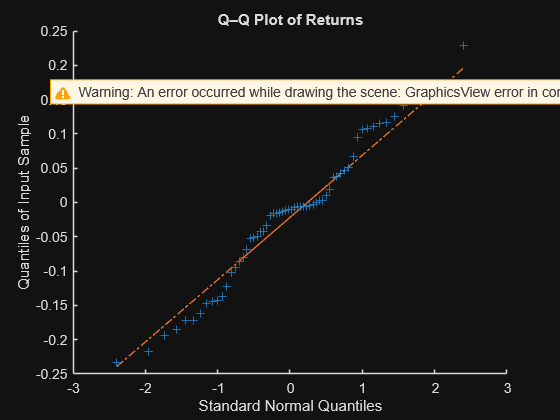

% Q-Q Plot (Normality)
qqplot(neste_return)
title('Q–Q Plot of Returns')


%Jarque-Bera Test
[h_jb, p_jb] = jbtest(neste_return);

fprintf('Jarque Bera Test Statistic: %.4f | p-value: %.4f\n', h_jb, p_jb);

Jarque Bera Test Statistic: 0.0000 | p-value: 0.5000


Normality of the return series was examined using both graphical and formal methods. The Q–Q plot indicates that most observations lie close to the reference line, suggesting that the central part of the return distribution is approximately normal, with only mild deviations in the tails. Consistent with this visual evidence, the Jarque–Bera test fails to reject the null hypothesis of normality, indicating no strong statistical evidence against a normal distribution. These results suggest that the unconditional distribution of returns is reasonably well behaved. However, normality alone does not imply independence or constant variance, and further time-series diagnostics are required to determine whether the data exhibit serial dependence or volatility clustering and to assess the suitability of ARMA or GARCH models.

%Stationarity Tests
[h_adf, p_adf] = adftest(neste_return); %Augmented Dickey-Fuller
fprintf('ADF Test Statistic:%.4f | p-value: %.4f\n', h_adf, p_adf);

ADF Test Statistic:1.0000 | p-value: 0.0010



[h_kpss, p_kpss] = kpsstest(neste_return);
fprintf('KPSS Test Statistic:  %.4f | p-value: %.4f\n', h_kpss, p_kpss);

KPSS Test Statistic:  0.0000 | p-value: 0.1000


With regards to the stationarity of the monthly returns, the Augmented Dickey Fuller Test rejects the null hypothesis of the presence of a unit root and the Kwiatkowski-Phillips-Schmidt-Shin(KPSS) test fails to reject its null hypothesis of presence of stationarity. It can be concluded that through these test the monthly return data is stationary.

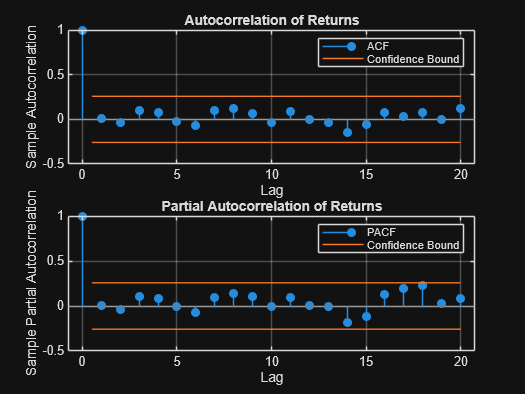

%Test for Aucorrelation (Does the data have a constant Autocovariance Structure)
figure(2)
% Plot the autocorrelation function
subplot(2,1,1);
autocorr(neste_return);
title('Autocorrelation of Returns');
subplot(2,1,2)
parcorr(neste_return)
title('Partial Autocorrelation of Returns');


% Perform a Ljung-Box test for autocorrelation
[h_lb, p_lb] = lbqtest(neste_return);
fprintf('Ljung-Box Test Statistic: %.4f | p-value: %.4f\n', h_lb, p_lb);

Ljung-Box Test Statistic: 0.0000 | p-value: 0.9842



[h_lb_2, p_lb_2] = lbqtest(neste_return.^2, 'Lags',12);
fprintf('Ljung-Box Test Statistic: %.4f | p-value: %.4f\n', h_lb_2, p_lb_2);

Ljung-Box Test Statistic: 0.0000 | p-value: 0.8568


%Test for Homoscedasticity (Does the data have a constant variance that is homoscedastic)
[h_arch, p_arch] = archtest(neste_return);
fprintf('ARCH Test Statistic: %.4f | p-value: %.4f\n', h_arch, p_arch);

ARCH Test Statistic: 0.0000 | p-value: 0.1538


Focusing on the autocovariance structure, From both the autocorrelation coeffiocient function and partial autocorrelation coefficients function plots, there is no visible autocorrelation in the monthly returns. The Ljung Box test also supports this accepting its null hypothesis of no presence of autocorrelation in the data. This phenomenon suggests a revisiting of the model chosen for this analysis as for ARMA models to be used, the timeseries has to have a constant mean, constant variance, and a constant autocovariance structure. In this timeseries case, there are constant mean, constant variance (it is homoscedastic as shown in the ARCH test), but it has no autocovariance structure suggesting that the data could be a constant mean white noise. 

This situation could suggest that predictability does not lie in returns but in volatility instead. But there is no ARCH Effect, even the GARCH model can not be used on such data. Hence, any model gotten from this data will add no predictive power and there is a high risk of overfitting.

Just to be clear and sure of the outcome of the exploratory analysis, we could proceed to still trying to fit the ARMA Model using the Box-Jenkins Approach.

## Data Modelling

Following the Box-Jenkins Apporoach

- Identifying the Order of the model

The order of the model can not exactly be determined from the plots as they both exhibit a geometrical decaying relationship precisely a sine damped wave, as a rough conclusion one could suspect the presence of a combined ARMA Model as both the acf and pacf plots are geometrically declining. In this kind of situation, the order of the model could be best determined using the Information Criteria precisely Aikaike's Information Criterion and Schwarz Bayesian Information Criterion.

%To construct the values of the information criteria AIC and BIC for any 
% combination of orders of AR and MA models, a for loop we used to generate
% both the AIC and BIC value at different lags, the lag that minimises the
% value of the Information Criterion will provide the order of the model.
maxorder=5;
AIC=[];
BIC=[];
for i=0:maxorder
    for j=0:maxorder
        model = arima(i,0,j); %i is the index of the AR order, j is the index of the MA order - in each matrix the element ij corresponds to a ARMA(i-1,j-1) model
        [EstMdl,EstParamCov,logL,info] = estimate(model,neste_return,'Display','off');
        [aic,bic] = aicbic(logL,length(info.X),size(neste_return,1));
        AIC(i+1,j+1)=aic;
        BIC(i+1,j+1)=bic;
    end
end
AIC

AIC =  -100.2298  -98.2374  -96.3022  -95.0462  -93.2072  -91.3678
  -98.2369  -99.1033  -97.2187  -93.1288  -91.2607  -89.4204
  -96.3063  -98.0823 -101.0500 -104.5914 -103.1220 -102.0870
  -95.0429  -93.2347 -104.4802  -96.8131  -96.0132  -94.6025
  -93.4650  -91.4757 -103.2107 -102.4328 -100.7788 -104.4482
  -91.4672  -95.8900  -96.7811 -103.0570  -99.0092 -104.1363


min(min(AIC)) %AIC generally suggests larger models

ans = -104.5914

BIC

BIC =   -96.0411  -91.9544  -87.9248  -84.5745  -80.6412  -76.7074
  -91.9539  -90.7259  -86.7470  -80.5627  -76.6003  -72.6657
  -87.9289  -87.6106  -88.4840  -89.9310  -86.3672  -83.2379
  -84.5712  -80.6686  -89.8198  -80.0584  -77.1641  -73.6590
  -80.8989  -76.8153  -86.4559  -83.5837  -79.8353  -81.4104
  -76.8068  -79.1352  -77.9320  -82.1136  -75.9714  -79.0041


min(min(BIC)) %AIC generally suggests smaller models

ans = -96.0411


% Creating text output for both Information Criteria.
[M,I] = min(AIC(:));
[I_row, I_col] = ind2sub(size(AIC),I);
OUTPUT=['AIC: ARMA(' , num2str(I_row-1) , ',' , num2str(I_col-1) , ')'];
disp(OUTPUT)

AIC: ARMA(2,3)


[M,I] = min(BIC(:));
[I_row, I_col] = ind2sub(size(BIC),I);
OUTPUT=['BIC: ARMA(' , num2str(I_row-1) , ',' , num2str(I_col-1) , ')'];
disp(OUTPUT)

BIC: ARMA(0,0)


The information criteria provide different model suggestions due to their treatment of model complexity. The AIC selects an ARMA(2,3) model, indicating that allowing for more parameters improves in-sample fit. In contrast, the BIC selects an ARMA(0,0) model, reflecting its stronger penalty for model complexity, especially in finite samples. Given the absence of significant autocorrelation in the return series and the relatively limited sample size, the BIC result is preferred, as it favors a more parsimonious specification and reduces the risk of overfitting. Consequently, the ARMA(0,0) model, corresponding to a constant mean process, is adopted for subsequent analysis.

- Model Estimation and Diagnostic Check.

model_monthly_r=arima(0,0,0);

 
    ARIMA(0,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.018075       0.013106       -1.3791         0.16785
    Variance     0.010306      0.0020489        5.0299      4.9074e-07



The return series was estimated using an ARMA(0,0) model, which implies that returns follow a constant mean process with no dependence on past values. Formally, the model can be written 

rt= μ+ εt

where rt� denotes the return at time t, μ is the constant mean, and εtt� is a white-noise error term. The estimated mean return is μ=−0.0181, with a p-value of 0.168, indicating that it is not statistically different from zero. This suggests that average returns cannot be predicted in a meaningful way. In contrast, the variance estimate is statistically significant, confirming that the return series is volatile. These results are consistent with the earlier autocorrelation tests and information criteria, which favored a parsimonious ARMA(0,0) specification.

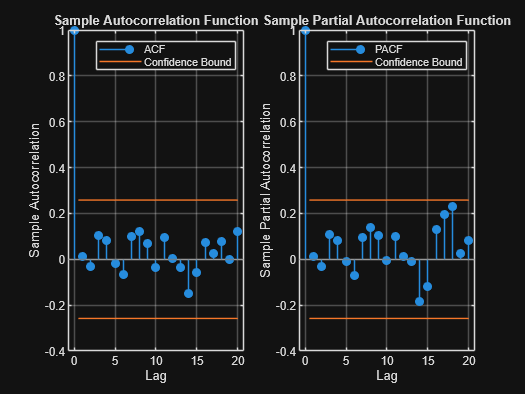

[E,V,logL] = infer(EstMdl1,neste_return); %residuals are stored in E now


subplot(1,2,1)
autocorr(E) %plots the autocorrelation function for E
subplot(1,2,2)
parcorr(E) %plots the partial autocorrelation function for E


%test for the autocorrelation of residuals
[h,P_val] = lbqtest(E) %h = 0 then it's good, if h = 1, it's not good and there is autocorrelation

h = logical
   0


P_val = 0.9842

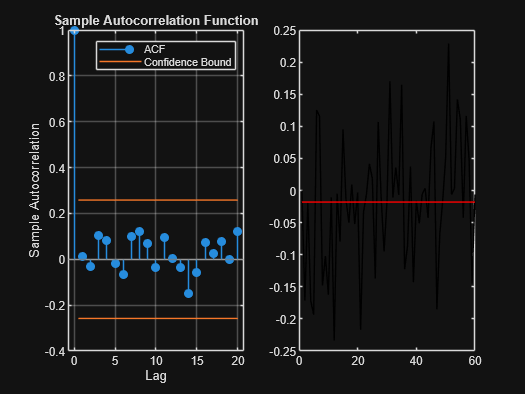


%The best model is ARMA(0,0)

% Lets see how the model performs graphically
plot(neste_return,'black')
hold on
plot(neste_return-E,'red') %this plots the FITTED VALUES represented as real values modified by the residuals
hold off

The adequacy of the model was assessed using residual diagnostics. The autocorrelation and partial autocorrelation functions of the residuals show that all sample autocorrelations lie within the 95% confidence bounds, indicating no remaining serial correlation. This visual evidence is supported by the Ljung–Box test, which fails to reject the null hypothesis of no autocorrelation (p-value = 0.984).The autocorrelation function of the residuals shows that all autocorrelations lie within the confidence bounds, indicating no remaining serial correlation after model estimation. This suggests that the model has successfully captured any linear dependence in the data. The residual time-series plot shows random fluctuations around zero with no visible structure or trend, consistent with white-noise behavior. Overall, these results indicate that the model is well specified with respect to the conditional mean.

- Predictions and Model Evaluation

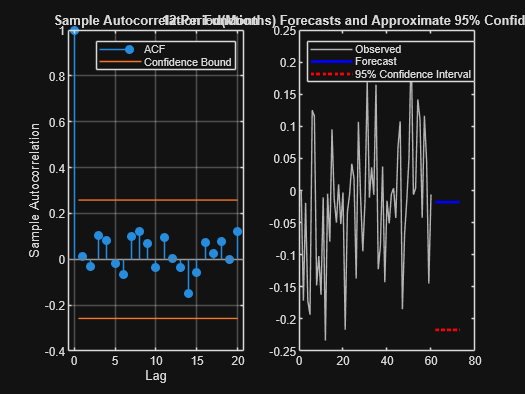

%Forecasting
%Let X= forecaste values and Y be the actual Values


data_2=xlsread("Neste Oyj Stock Price History.xlsx","Neste Oyj StockReturn2025Month","A2:H13");
Y=data_2(:,7);
N=length(Y);

[X,XMSE] = forecast(EstMdl1, N ,'Y0',neste_return);

h1 = plot(neste_return,'Color',[.7,.7,.7]);
hold on
h2 = plot(62:73,X,'b','LineWidth',2);
h3 = plot(62:73,X + 1.96*sqrt(XMSE),'r:',...
		'LineWidth',2);
plot(62:73,X - 1.96*sqrt(XMSE),'r:','LineWidth',2);
legend([h1 h2 h3],'Observed','Forecast',...
		'95% Confidence Interval','Location','NorthWest');
title(['12-Period(Months) Forecasts and Approximate 95% '...
			'Confidence Intervals'])
hold off


%Evaluation of Model

err= Y-X

err =     0.0181
    0.1449
   -0.0577
    0.1590
    0.0117
    0.1435
    0.2016
    0.2161
    0.0492
    0.0893
    0.0099
   -0.3341


MAE_m = mean(abs(err));
MSE_m = mean(err.^2);

fprintf('ARMA Return Forecast Evaluation (2025):\n')

ARMA Return Forecast Evaluation (2025):


fprintf('MAE = %.6f\n', MAE_m)

MAE = 0.119597


fprintf('MSE = %.6f\n', MSE_m)

MSE = 0.023343


Forecasts generated from the ARMA(0,0) model are constant over time and equal to the estimated mean return, reflecting the absence of predictability in the conditional mean. The 95% confidence intervals are relatively wide, which highlights the high uncertainty associated with return forecasts. Model performance was evaluated using Mean Absolute Error (MAE) and Mean Squared Error (MSE) for the 2025 forecast period. The obtained values, MAE = 0.116 and MSE = 0.023, indicate sizable forecast errors relative to the magnitude of the mean return. This outcome is expected in financial return data and confirms that, while the model is statistically well specified, its ability to predict individual returns is limited.

The lack of predictability in monthly returns may be explained by both economic and statistical factors. Financial markets are generally considered to be informationally efficient, meaning that publicly available information is quickly incorporated into prices, leaving little scope for forecasting average returns. In addition, the use of monthly data results in a relatively small sample size, which reduces the power of statistical tests and makes it difficult to detect weak dynamic patterns. Monthly aggregation may also smooth short-term movements that occur within the month, further obscuring potential dependence. To address these limitations, the analysis can be extended using daily data, which provides a much larger number of observations and allows for a more detailed examination of return dynamics. Daily data are better suited for identifying volatility clustering and other time-varying features, and therefore offer a more appropriate framework for models such as GARCH, which focus on forecasting risk rather than mean returns.